close all;
clear variables;


## Калибровка

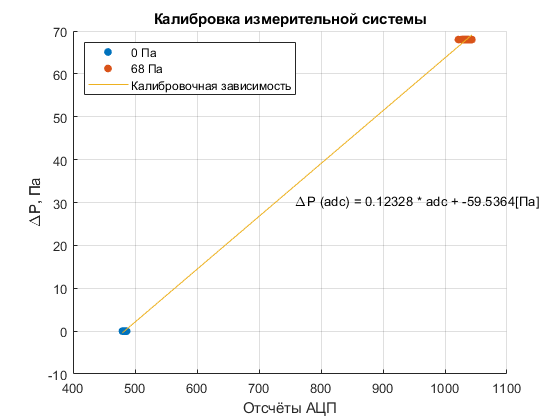


zpA = dlmread('D:\Documents\jet\2-experimentData\calibzero1.txt');
npA = dlmread('D:\Documents\jet\2-experimentData\calib1.txt');

zp = zpA(:,2);
np = npA(:,2);

fclose('all');

zero = ones(length(zp), 1) * 0;
press = ones(length(np), 1) * 68;

cAdc = [zp; np];
cPrs = [zero; press];

c = polyfit(cAdc, cPrs, 1);

cFigure = figure('Name', 'Калибровка измерительной ситемы', 'NumberTitle', 'off');
hold all;

plot(zp, zero, '.', 'MarkerSize', 20);
plot(np, press, '.', 'MarkerSize', 20);

plot(cAdc, polyval(c, cAdc));

legend('0 Па', '68 Па','Калибровочная зависимость', 'Location', 'NorthWest');

grid on;
xlabel('Отсчёты АЦП');
ylabel('\DeltaР, Па');
title('Калибровка измерительной системы');
text(mean(cAdc), mean(cPrs) * 0.9, ['\DeltaP (adc) = ', num2str(c(1)), ' * adc + ', num2str(c(2)), '[Па]']);

saveas(cFigure, 'D:\Documents\jet\kalibr.png');

## Загрузка данных

mm01 = load('D:\Documents\jet\2-experimentData\01mm.dat');
mm11 = load('D:\Documents\jet\2-experimentData\11mm.dat');
mm21 = load('D:\Documents\jet\2-experimentData\21mm.dat');
mm31 = load('D:\Documents\jet\2-experimentData\31mm.dat');
mm41 = load('D:\Documents\jet\2-experimentData\41mm.dat');
mm51 = load('D:\Documents\jet\2-experimentData\51mm.dat');
mm61 = load('D:\Documents\jet\2-experimentData\61mm.dat');
mm71 = load('D:\Documents\jet\2-experimentData\71mm.dat');

dx = 0.25;
x = mm01(:,1)' * 0.25;

p01 = polyval(c, mm01(:, 2));
p11 = polyval(c, mm11(:, 2));
p21 = polyval(c, mm21(:, 2));
p31 = polyval(c, mm31(:, 2));
p41 = polyval(c, mm41(:, 2));
p51 = polyval(c, mm51(:, 2));
p61 = polyval(c, mm61(:, 2));
p71 = polyval(c, mm71(:, 2));

pressure = [p01, p11, p21, p31, p41, p51, p61, p71];
zNames = {'1 мм'; '11 мм'; '21 мм'; '31 мм'; '41 мм'; '51 мм'; '61 мм'; '71 мм'}

zNames = 8×1 cell array
    {'1 мм' }
    {'11 мм'}
    {'21 мм'}
    {'31 мм'}
    {'41 мм'}
    {'51 мм'}
    {'61 мм'}
    {'71 мм'}


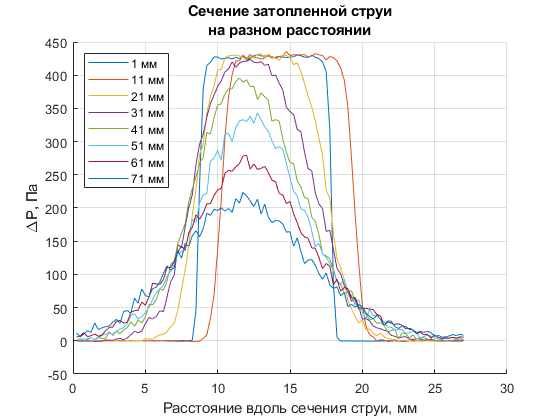


f2 = figure();
hold on;
grid on;
title({'Сечение затопленной струи', 'на разном расстоянии'});
ylabel('\DeltaP, Па');
xlabel('Расстояние вдоль сечения струи, мм');

for i = 1:size(pressure, 2)
    plot(x, pressure(:, i), 'DisplayName', zNames{i});
end

legend('Location', 'NorthWest');

saveas(f2, 'D:\Documents\jet\press.png');

## Центровка графика

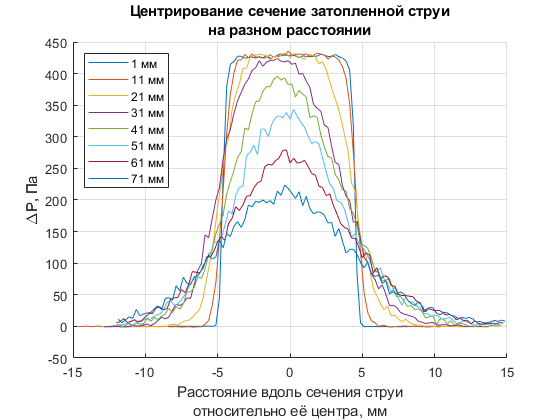

f3 = figure();
hold on;
grid on;
title({'Центрирование сечение затопленной струи', 'на разном расстоянии'});
ylabel('\DeltaP, Па');
xlabel({'Расстояние вдоль сечения струи', 'относительно её центра, мм'});

xCentered = zeros(size(pressure));
offset = 50;

for i = 1:size(pressure, 2)
    right = x(find(pressure(:, i) > offset, 1, 'last'));
    left = x(find(pressure(:, i) > offset, 1));
    
    center = left + (right - left) / 2;
    xCentered(:, i) = x - center;
    
    plot(xCentered(:, i), pressure(:, i), 'DisplayName', zNames{i});
end

legend('Location', 'NorthWest');

saveas(f3, 'D:\Documents\jet\pressCentered.png')

## Трёхмерный график

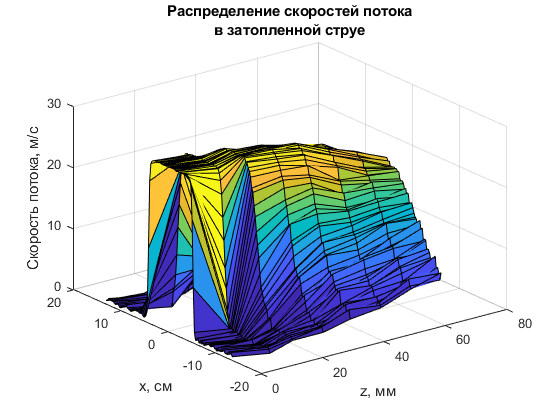

f4 = figure;

u = sqrt((abs(pressure) * 2) / 1.2);

z = zeros(size(u, 1), size(u, 2));

for i = 1:size(u, 1)
    for j = 1:size(u, 2)
        z(i, j) = (j - 1) * 10 + 1;
    end
end



for i = 1:size(z, 2)
    right = x(find(pressure(:, i) > offset, 1, 'last'));
    left = x(find(pressure(:, i) > offset, 1));
    
    center = left + (right - left) / 2;
    xCentered(:, i) = x - center;
    
end

surf(z, xCentered, u);

hold on;
grid on;
title({'Распределение скоростей потока', 'в затопленной струе'});
zlabel('Скорость потока, м/с');
xlabel('z, мм');
ylabel('x, мм');

saveas(f4, 'D:\Documents\jet\pressCGraph3.png')

## Расход

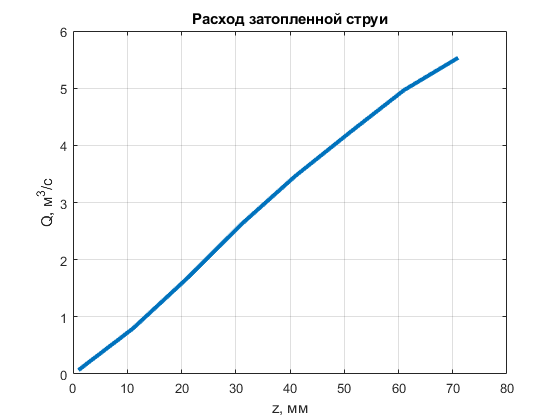

f5 = figure;

x = [1, 11, 21, 31, 41, 51, 61, 71];

y = zeros(size(x));

for i = 1:size(y, 2)
    sum = 0;
    for k = 1:size(u, 1)
        sum = sum + u(k, i) * x(i);
    end
    y(i) = 2 * 3.14 / 1.2 * (sum/2) * 0.000025;
end

plot(x, y, 'LineWidth', 3);
hold on;
grid on;
title('Расход затопленной струи');
xlabel('z, мм');
ylabel('Q, м^3/c');

saveas(f5, 'D:\Documents\jet\q.png')